Definicja prostego modelu ACC po wprowadzeniu sterowania:


$$\left\lbrack \begin{array}{c}
{\dot{x} }_1 \\
{\dot{x} }_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
v\\
-\frac{k}{m}\left(v-v_0 \right)
\end{array}\right\rbrack$$


syms x v v0 real
syms M K real positive
f = [v; -K*(v-v0)/m];

Szukamy punktów równowagi:

solve(f == [0;0], {x,v}, ReturnConditions=true)

ans = struct with fields:
             x: [0×1 sym]
             v: [0×1 sym]
    parameters: [1×0 sym]
    conditions: [0×1 sym]


Definicja funkcji Lapunowa:


$$V(x) = \frac{(v-v_0)^2}{2}$$


V = (v-v0)^2/2;

Wyznaczenie pochodnej po trajektoriach systemu:

Vdot = simplify(gradient(V, [x;v])' * f);
fprintf("Pochodna po trajektoriach systemu: %s", string(Vdot));

Pochodna po trajektoriach systemu: -(100*K*(v - v0)^2)/71

Wyrysowanie portretu fazowego i funkcji Lapunowa oraz obszaru przyciągania:

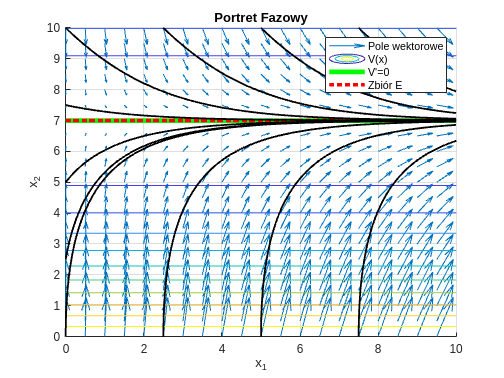

k = 2.9;
m = 0.71;
V0 = 7;

[X, V] = meshgrid(0:0.5:10);
dX = X;
dV = -k*(V-V0)/m;

Vfun = @(x,v)(v-V0).^2/2;
Vnum = (V-V0).^2/2;
Vdotnum = -k*(V-V0).^2/2;

figure();
grid on;
hold on;
xlabel("x_1");
ylabel("x_2");
title("Portret Fazowy");
xlim([0, 10]);
ylim([0, 10]);
legend("show");

quiver(X, V, dX, dV, 2, "DisplayName", "Pole wektorowe");

X0 = {2.5*[0;4], 2.5*[1;4], 2.5*[2;4], 2.5*[3;4], 2.5*[4;4], ...
    2.5*[0;0], 2.5*[1;0], 2.5*[2;0], 2.5*[3;0], 2.5*[4;0], ...
    2.5*[0;0], 2.5*[0;1], 2.5*[0;2], 2.5*[0;3], 2.5*[0;4], ...
    2.5*[4;0], 2.5*[4;1], 2.5*[4;2], 2.5*[4;3], 2.5*[4;4]};

f_num = @(t, x)[x(2);-k*(x(2)-V0)/m];

for index = 1:length(X0)
    x0 = X0{index};
    [~, y] = ode45(f_num,0:0.01:20, x0);
    z = Vfun(y(:, 1), y(:, 2));
    plot3(y(:, 1), y(:, 2), z, "k", "LineWidth", 1.5, "HandleVisibility", "off");
end
% Wyrysowanie funkcji Lapunowa
contour(X, V, Vnum, 10, "DisplayName", "V(x)");
% Zaznaczenie punktów równowagi
contour(X, V, Vnum, [0.0001,0.0001], "g", "LineWidth", 4, "DisplayName", "V'=0");
% Zaznaczenie zbioru E
contour(X, V, Vdotnum, [0,0], "r:", "LineWidth", 3, "DisplayName", "Zbiór E");


% Znalezienie zbioru M - największy inwariantny w E (czyli x \in R, v = v0)
% Musimy znaleźć gdzie x' = 0, żeby pozostać na prostej v = v0
f_m = subs(f, {v0,K,M}, {V0,k,m});
v_dot = f_m(2); % <- niezależne od x, zatem jeśli trajektoria rozpocznie się na v0, to pozostanie na tej prostej
